# Continuous System Equivalence

Prepared for EGLM03 Modern Control Systems by Chris P. Jobling

## Example


$$G(s) = \frac{a}{s + a}$$


Let a = 1

a = 1;
% Then
Gs = tf([a],[1, a])


Gs =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



## Sample period

Ts = 1/10; % seconds

## Hold equivalent

Gz_zoh = c2d(Gs, Ts, 'zoh')


Gz_zoh =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



This is also default

Gz_zoh = c2d(Gs, Ts)


Gz_zoh =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Plot Result

step(Gs,'-',Gz_zoh,'--')

## Approximation by numerical-integration

also known as bilinear transform or Tustin equivalent

Gz_tustin = c2d(Gs, Ts, 'tustin')


Gz_tustin =
 
  0.04762 z + 0.04762
  -------------------
      z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Plot Result

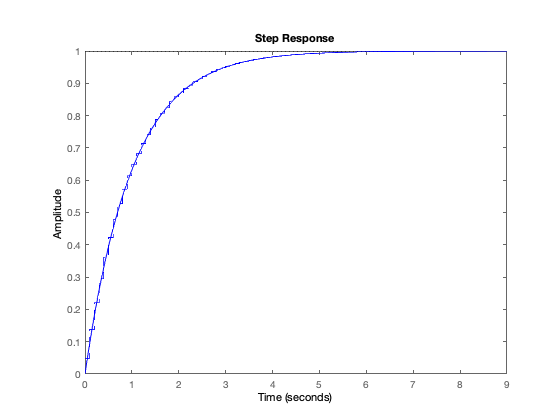

step(Gs,'-',Gz_tustin,'--')

% Matched pole-zero mapping
Gz_mpz = c2d(Gs, Ts, 'matched')


Gz_mpz =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Plot result

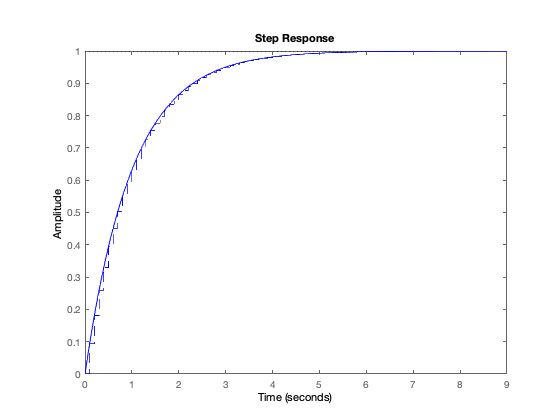

step(Gs,'-',Gz_mpz,'--')

## Other supported equivalents?

help c2d

 C2D  Converts continuous-time dynamic system to discrete time.
 
    SYSD = C2D(SYSC,TS,METHOD) computes a discrete-time model SYSD with 
    sample time TS that approximates the continuous-time model SYSC.
    The string METHOD selects the discretization method among the following:
       'zoh'           Zero-order hold on the inputs
       'foh'           Linear interpolation of inputs
       'impulse'       Impulse-invariant discretization
       'tustin'        Bilinear (Tustin) approximation.
       'matched'       Matched pole-zero method (for SISO systems only).
       'least-squares' Least-squares minimization of the error between
                       frequency responses of the continuous and discrete 
                       systems (for SISO systems only).
    The default is 'zoh' when METHOD is omitted. The sample time TS should 
    be specified in the time units of SYSC (see "TimeUnit" property).
 
    C2D(SYSC,TS,OPTIONS) gives access to additional discretization option